G = tf([1 1], [1 10 0]); % função de malha aberta
poles_ma = pole(G); % polos de malha aberta
zeros_ma = zero(G); % zeros de malha aberta

T = feedback(G, 1); % fechar a malha com realimentação unitária
poles_mf = pole(T); % polos de malha fechada
zeros_mf = zero(T); % zeros de malha fechada

% Exibir
disp('=== MALHA ABERTA ===');

=== MALHA ABERTA ===


disp('Função:');

Função:


G

G =
 
    s + 1
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


disp('Polos: '); 

Polos: 


disp(poles_ma);

     0
   -10



disp('Zeros: ');

Zeros: 


disp(zeros_ma);

    -1



disp('Resposta ao Degrau: ');

Resposta ao Degrau: 


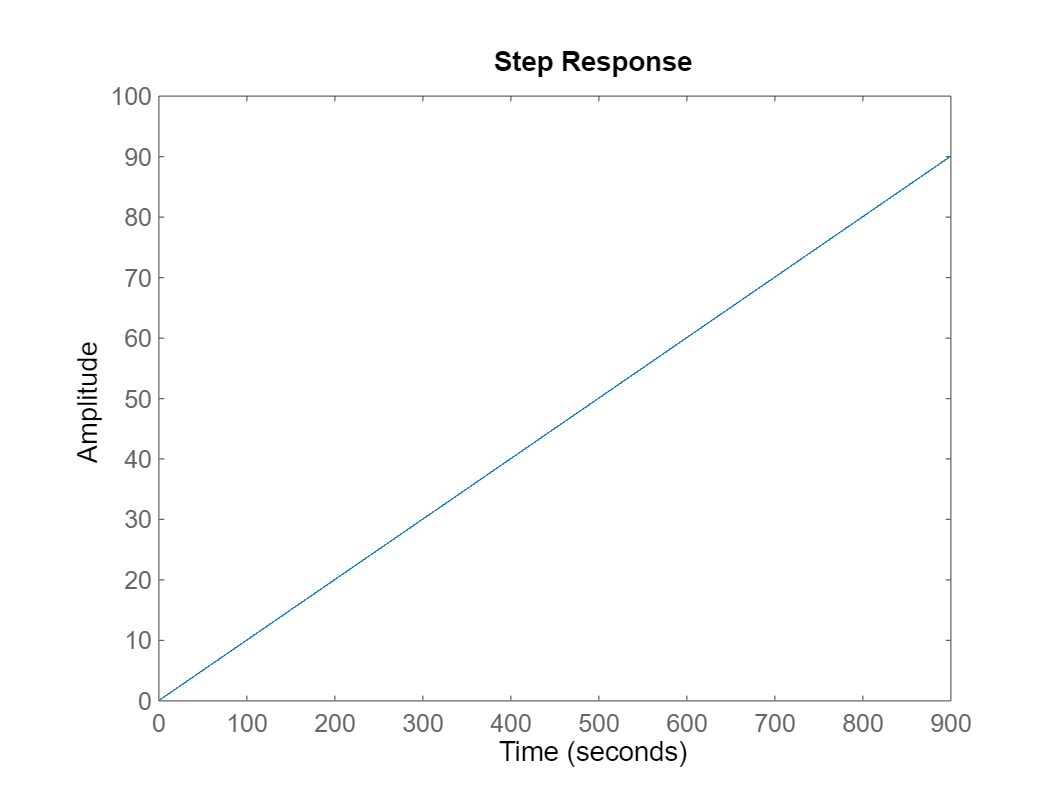

step(G);

disp('Conclusão: Observa-se um sistema instável, pois possui um polo na origem (para ser estável devia estar no semiplano esquerdo)')

Conclusão: Observa-se um sistema instável, pois possui um polo na origem (para ser estável devia estar no semiplano esquerdo)



disp('=== MALHA FECHADA ===');

=== MALHA FECHADA ===


disp('Função:');

Função:


T

T =
 
      s + 1
  --------------
  s^2 + 11 s + 1
 
Continuous-time transfer function.
Model Properties


disp('Polos: '); 

Polos: 


disp(poles_mf);

  -10.9083
   -0.0917



disp('Zeros: ');

Zeros: 


disp(zeros_mf);

    -1



disp('Resposta ao Degrau: ');

Resposta ao Degrau: 


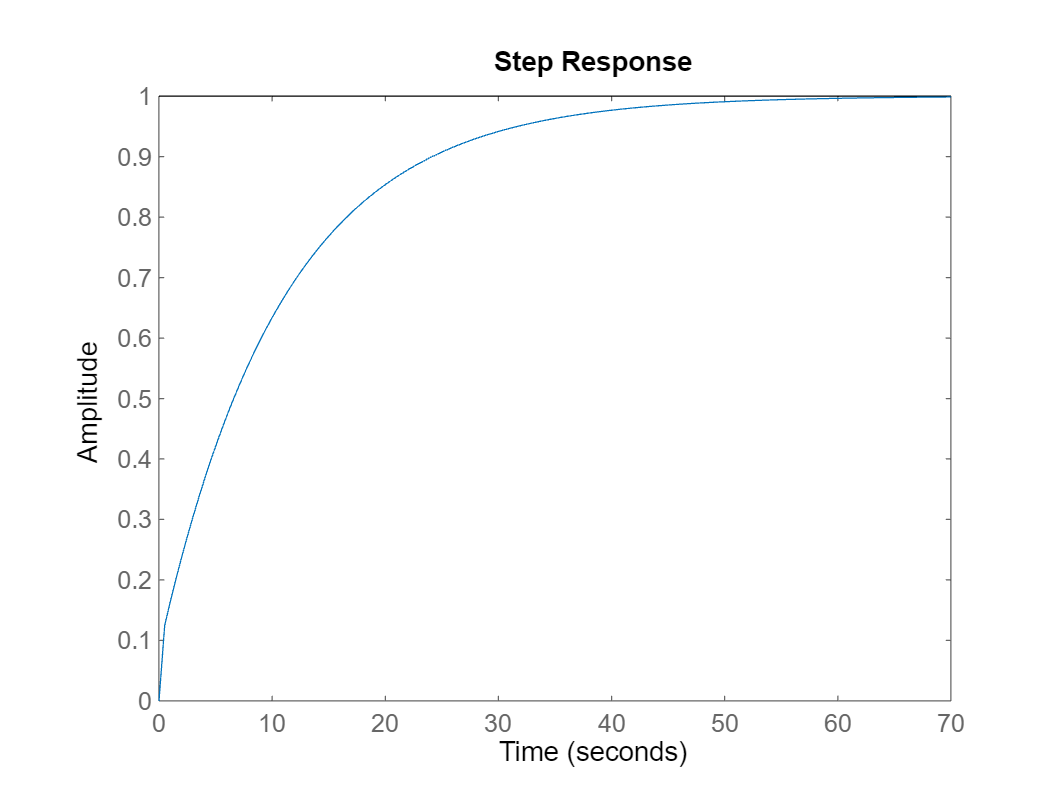

step(T);